# DIY Solution: Example on slide 10

clear all; close all; clc

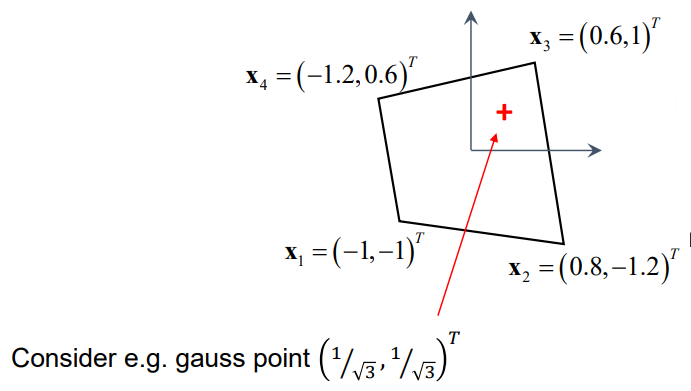

% ELEMENT
%  4   --   3 
%  |     X  |
%  |        | 
%  1   --   2

x1 = [-1    ,  -1];
x2 = [ 0.8  ,-1.2];
x3 = [ 0.6  ,   1];
x4 = [-1.2  , 0.6];

x = [x1;x2;x3;x4];

### Step 1:

Gauss points r_g, s_g

Here: First: We only consider one gauss point.

r_g = 1/sqrt(3);
s_g = 1/sqrt(3);

### Step 2:

Derivatives of shape functions w.r.t. r,s,t

[h, dh] = linearShapeFunctions( r_g, ...
                                s_g)

h =     0.0447    0.1667    0.6220    0.1667


dh =    -0.1057    0.1057    0.3943   -0.3943
   -0.1057   -0.3943    0.3943    0.1057


### Step 3:

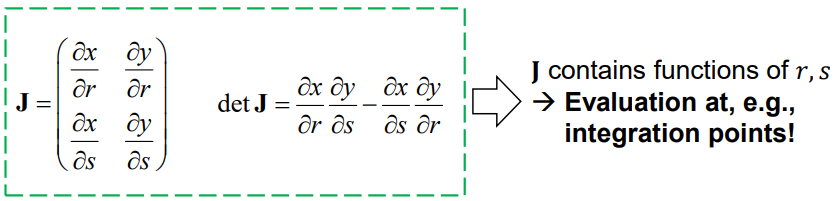

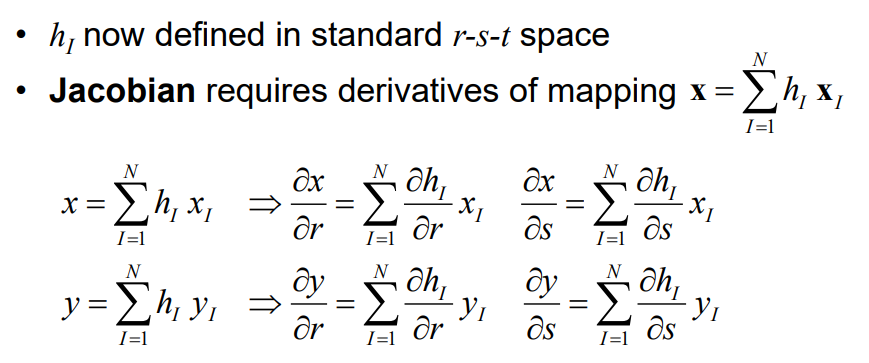

#### a) Jacobian

J = dh * x

J =     0.9000    0.1366
   -0.1000    1.0366


#### b) Determinant

detJ = det(J)

detJ = 0.9466

#### c) Inverse

invJ = inv(J)

invJ =     1.0951   -0.1443
    0.1056    0.9508


### Step 4:

#### B-matrix

dhdx = invJ*dh;
B    = bMatrix(dhdx)

B =    -0.1005         0    0.1726         0    0.3749         0   -0.4471         0
         0   -0.1116         0   -0.3638         0    0.4166         0    0.0588
   -0.1116   -0.1005   -0.3638    0.1726    0.4166    0.3749    0.0588   -0.4471


### Step 5:

#### Stiffness-matrix

Ke  = zeros(8);

E   = 2.1e5; nu = 0.3;
C   = E / (1 - nu^2) * [1, nu, 0;
                        nu, 1, 0;
                        0,  0, (1 - nu) / 2];
B   = B(:,[5:6])

B =     0.3749         0
         0    0.4166
    0.4166    0.3749


Ke = B' * C * B * abs(detJ)

Ke = 1.0e+04 *

    4.3975    2.2177
    2.2177    4.8657


function [h, dh] = linearShapeFunctions(r, s)
    % Evaluate shape functions for linear quadrilateral element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)           Shape functions at (r, s), row per given point
    %   dh (array)          Derivatives of shape functions at first (r, s)
    h1 = 1/4 * (1 - r) .* (1 - s);
    h2 = 1/4 * (1 + r) .* (1 - s);
    h3 = 1/4 * (1 + r) .* (1 + s);
    h4 = 1/4 * (1 - r) .* (1 + s);

    dh1dr = -1/4 * (1 - s);
    dh1ds = -1/4 * (1 - r);
    dh2dr = 1/4 * (1 - s);
    dh2ds = -1/4 * (1 + r);
    dh3dr = 1/4 * (1 + s);
    dh3ds = 1/4 * (1 + r);
    dh4dr = -1/4 * (1 + s);
    dh4ds = 1/4 * (1 - r);

    h = [h1, h2, h3, h4];
    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds;
          dh4dr, dh4ds]';
end

function B = bMatrix(dhdx)
    % Evaluate B matrix for linear quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   B (array)   B matrix for linear quadrilateral element in natural coordinates

    % Initialize B matrix
    B = zeros(3, 8);

    % Define linear indices for first B matrix -> B1 corresponding to node 1
    indicesBi = [1; 5; 3; 6];
    indicesdHi = [1; 2; 2; 1];

    % Repeat indices for node 2 to node 4
    indicesB = indicesBi + (0 : 6 : 6 * 4 - 6);
    indicesdH = indicesdHi + (0 : 2 : 4 * 2 - 2);

    % Assign dh entries to B matrix
    B(indicesB) = dhdx(indicesdH);
end